# 简化模型平衡控制

## 0 准备工作

[简化模型动力学分析](matlab:open('./simplified_dynamic.mlx'))

run("./simplified_dynamic.mlx");

## 1 机器人参数

param = struct( ...
  'g',9.81, ...
  'm_w',1.01, ...
  'I_w',1248e-6, ...
  'm_l',4, ...
  'I_l',13696e-6, ...
  'm_b',14.76, ...
  'I_b',268943e-6, ...
  'R_w',60e-3, ...
  'l_w',0.12, ...
  'l_b',0.12, ...
  'l_c',1e-3); % -7e-3~10e-3

A = double(subs(A_sym,{g,m_w,I_w,m_l,I_l,m_b,I_b,R_w,l_w,l_b,l_c}, ...
  {param.g,param.m_w,param.I_w,param.m_l,param.I_l,param.m_b,param.I_b, ...
   param.R_w,param.l_w,param.l_b,param.l_c}));
B = double(subs(B_sym,{g,m_w,I_w,m_l,I_l,m_b,I_b,R_w,l_w,l_b,l_c}, ...
  {param.g,param.m_w,param.I_w,param.m_l,param.I_l,param.m_b,param.I_b, ...
   param.R_w,param.l_w,param.l_b,param.l_c}));
C = eye(6);

% linearized system model
ss_WLR = ss(A,B,C,0);

## 2 控制器设计

### 2.1 平衡控制

状态反馈控制器

$\mathbf{u}=K_{2\times6}(\mathbf{x}_d-\mathbf{x})$    (1)

状态反馈矩阵 K 通过 LQR 计算得到，代价函数

$J=\int_{0}^{\infty}\left(x^TQx+u^TRu\right)dx$    (2)

根据 LQR 可以得到状态反馈矩阵 K

$K=R^{-1}B^TP$    (3)

其中 P 满足 Riccati 方程

$A^TP+PA+PBR^{-1}B^TP+Q=0$    (4)

Q = diag([5,5e2,5e3,50,1e4,100]);
R = diag([10,1]);
K = lqr(ss_WLR,Q,R)

K =    -0.6738   -7.1017  -34.5667   -4.4942   -9.8158   -2.1156
    0.6780    7.0792   26.6372    3.3570  -95.2629  -11.2667


## 3 仿真验证

[simulink仿真](matlab:open('./balance_control_simple.slx'))

线性化模型仿真结果

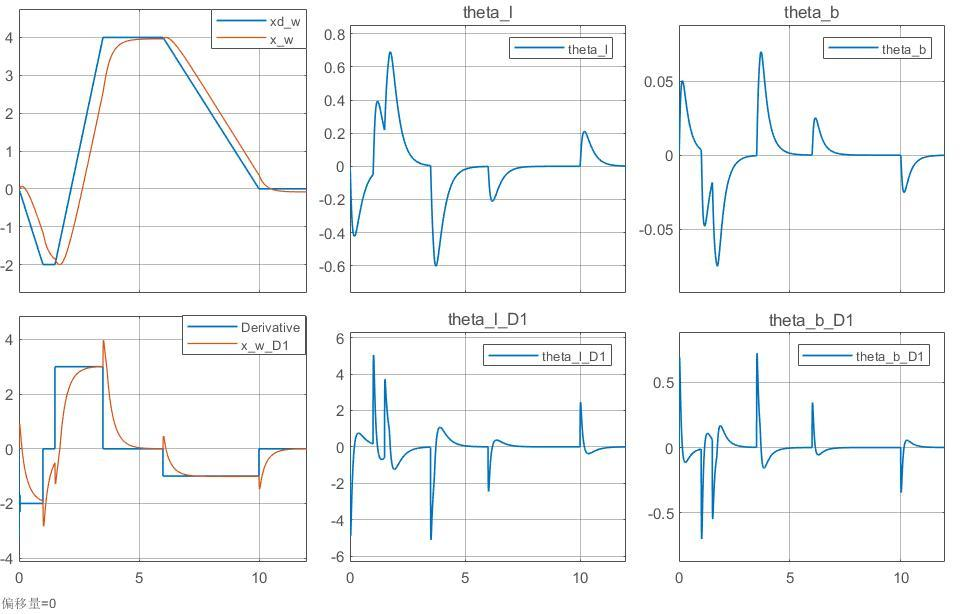

simscape仿真结果